# Foundations of Robotics- Final Project

## By Josephine Odusanya || N12594770 || joo9964@nyu.edu

Instructions :

Just press run. The code should load. 

## 1. Defining the Scope

Basic Requirements : 

- Perform Forward Kinematics

- Draw the robot 

- Perform Inverse Kinematics

## 2. Forward Kinematics

The forward kinematics function calculates the position and orientation of the robot's end-effector given the joint angles. This is achieved using the Denavit-Hartenberg (DH) convention and homogeneous transformation matrices.

### Build the DH Table

Inputs: 

    Theta - rotation (in radians)

    d - translation along the z-axis 

    a- translation along the x-axis

    alpha - rotation along the x-axis (in radians)

Output:

    T - 4x4 transformation matrix

### Define the parameters

%scaled down by 10
l1 = 26.7;
l2 = 28.45;
l3 = 5.35;
l4 = 34.25;
l5 = 7.6;
l6 = 9.7;

theta = [pi/2, pi, 0, pi, -pi, 0];
d = [l1, 0, 0, l4, 0, l6];
a = [0, 28.9489, 7.75, 0, l5, 0];
alpha = [-pi/2, 0, -pi/2, pi/2, -pi/2, 0];


### Building Transformation Matrix

T = eye(4);
T_i = cell(1,6);

for i = 1:6
    T_i{i} = [cos(theta(i)) -sin(theta(i))*cos(alpha(i)) sin(theta(i))*sin(alpha(i)) a(i)*cos(theta(i));
              sin(theta(i)) cos(theta(i))*cos(alpha(i)) -cos(theta(i))*sin(alpha(i)) a(i)*sin(theta(i));
              0 sin(alpha(i)) cos(alpha(i)) d(i); 
              0 0 0 1];
    T = T * T_i{i};
end

T0_6 = T;
disp('The DH transformation matrix is:');

The DH transformation matrix is:


disp(T0_6)

   -0.0000   -1.0000    0.0000   -0.0000
   -1.0000    0.0000    0.0000  -44.2989
   -0.0000   -0.0000   -1.0000   51.2500
         0         0         0    1.0000



### Compute the links

The final transformation matrix T0_6 is computed by multiplying these individual matrices:

T0_6=T0_1⋅T1_2⋅T2_3⋅T3_4⋅T4_5⋅T5_6*T*0_6=*T*0_1⋅*T*1_2⋅*T*2_3⋅*T*3_4⋅*T*4_5⋅*T*5_6

This matrix represents the position and orientation of the end-effector relative to the base frame.

T0_1 = T_i{1}

T0_1 =     0.0000   -0.0000   -1.0000         0
    1.0000    0.0000    0.0000         0
         0   -1.0000    0.0000   26.7000
         0         0         0    1.0000


T1_2 = T_i{1} * T_i{2}

T1_2 =    -0.0000    0.0000   -1.0000   -0.0000
   -1.0000   -0.0000    0.0000  -28.9489
   -0.0000    1.0000    0.0000   26.7000
         0         0         0    1.0000


T2_3 = T1_2 * T_i{3}

T2_3 =    -0.0000    1.0000   -0.0000   -0.0000
   -1.0000   -0.0000   -0.0000  -36.6989
   -0.0000         0    1.0000   26.7000
         0         0         0    1.0000


T3_4 = T2_3 * T_i{4}

T3_4 =     0.0000   -0.0000    1.0000   -0.0000
    1.0000   -0.0000   -0.0000  -36.6989
    0.0000    1.0000    0.0000   60.9500
         0         0         0    1.0000


T4_5 = T3_4 * T_i{5}

T4_5 =    -0.0000   -1.0000    0.0000   -0.0000
   -1.0000    0.0000    0.0000  -44.2989
   -0.0000   -0.0000   -1.0000   60.9500
         0         0         0    1.0000


T5_6 = T4_5 * T_i{6}

T5_6 =    -0.0000   -1.0000    0.0000   -0.0000
   -1.0000    0.0000    0.0000  -44.2989
   -0.0000   -0.0000   -1.0000   51.2500
         0         0         0    1.0000



T0_6 = T0_1*T1_2*T2_3*T3_4*T4_5*T5_6

T0_6 =     0.0000    0.0000    1.0000   19.6989
   -0.0000   -1.0000    0.0000  -43.3511
    1.0000   -0.0000   -0.0000   63.2489
         0         0         0    1.0000


## 3. Visualization: Plotting the points

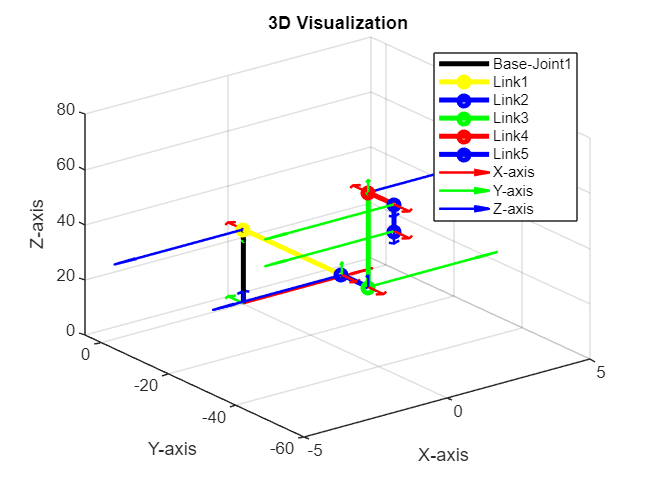

figure;
hold on;
grid on;
title('3D Visualization')
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

% Define colors for links and axes
link_colors = {'k', 'y', 'b', 'g', 'r', 'b'};
axis_colors = {'r', 'g', 'b'}; % Red for X, Green for Y, Blue for Z
axis_length = 5;

% Plot links
plot3([0, T0_1(1,4)], [0, T0_1(2,4)], [0, T0_1(3,4)], [link_colors{1} '-'], 'LineWidth', 3)
plot3([T0_1(1,4), T1_2(1,4)], [T0_1(2,4), T1_2(2,4)], [T0_1(3,4), T1_2(3,4)], [link_colors{2} '-o'], 'LineWidth', 3)
plot3([T1_2(1,4), T2_3(1,4)], [T1_2(2,4), T2_3(2,4)], [T1_2(3,4), T2_3(3,4)], [link_colors{3} '-o'], 'LineWidth', 3)
plot3([T2_3(1,4), T3_4(1,4)], [T2_3(2,4), T3_4(2,4)], [T2_3(3,4), T3_4(3,4)], [link_colors{4} '-o'], 'LineWidth', 3)
plot3([T3_4(1,4), T4_5(1,4)], [T3_4(2,4), T4_5(2,4)], [T3_4(3,4), T4_5(3,4)], [link_colors{5} '-o'], 'LineWidth', 3)
plot3([T4_5(1,4), T5_6(1,4)], [T4_5(2,4), T5_6(2,4)], [T4_5(3,4), T5_6(3,4)], [link_colors{6} '-o'], 'LineWidth', 3)

% Plot reference frames
joint_positions = {[0;0;0], T0_1(1:3,4), T1_2(1:3,4), T2_3(1:3,4), T3_4(1:3,4), T4_5(1:3,4), T5_6(1:3,4)};
transformations = {eye(4), T0_1, T1_2, T2_3, T3_4, T4_5, T5_6};

for i = 1:7
    current_pos = joint_positions{i};
    current_T = transformations{i};
    R = current_T(1:3, 1:3);
    
    for j = 1:3
        quiver3(current_pos(1), current_pos(2), current_pos(3), ...
            R(1,j)*axis_length, R(2,j)*axis_length, R(3,j)*axis_length, ...
            axis_colors{j}, 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
    end
end

legend('Base-Joint1', 'Link1', 'Link2', 'Link3', 'Link4', 'Link5', 'X-axis', 'Y-axis', 'Z-axis', 'Location', 'best');
view(3);
hold off;

## Inverse Kinematics

The inverse kinematics function calculates the joint angles required to achieve a desired end-effector position and orientation. This project uses a geometric approach combined with trigonometry.

These methods allow for the accurate computation of both forward and inverse kinematics, enabling the robot to move to desired positions and orientations in 3D space.

% Define offsets
offset_T2 = -1.384;
offset_T3 = -1.384;

% Inverse Kinematics function
function q = inverseKinematics(T0_6, offset_T2, offset_T3)
    % Extract position and orientation
    px = T0_6(1,4); py = T0_6(2,4); pz = T0_6(3,4);
    R = T0_6(1:3,1:3);
    
    % Calculate joint angles (with offsets)
    q1 = atan2(py, px)
    r = sqrt(px^2 + py^2);
    q2 = atan2(pz - 26.7, r - 28.9489) + offset_T2
    q3 = atan2(60.95 - pz, 44.2989 - r) + offset_T3
    
    % Wrist angles
    q4 = atan2(R(2,1), R(1,1))
    q5 = atan2(sqrt(R(3,1)^2 + R(3,2)^2), R(3,3))
    q6 = atan2(R(3,2), -R(3,1))
    
    q = [q1; q2; q3; q4; q5; q6];
end

% Calculate inverse kinematics with offsets
joint_angles = inverseKinematics(T0_6, offset_T2, offset_T3);

q1 = -1.1443

q2 = -0.2854

q3 = -3.9197

q4 = -0.2268

q5 = 1.5708

q6 = -3.1416

## References

- UFACTORY xArm 6 DoF Robotic Arm (6 DoF) - [https://www.robotshop.com/products/xarm-6-dof-robotic-arm?srsltid=AfmBOopPyiBaEuVl-cDxjGoZkpzS28sKnXH5GVZxOjf3XAPvWnr_pYeP](https://www.robotshop.com/products/xarm-6-dof-robotic-arm?srsltid=AfmBOopPyiBaEuVl-cDxjGoZkpzS28sKnXH5GVZxOjf3XAPvWnr_pYeP)

- Manipulator Differential Kinematics, J.Haviland, P.Corke - [https://magazines.ieee.org/ra/library/page/december_2024/155/?mkt_tok=NzU2LUdQSC04OTkAAAGXfqbzun0i2_TeMzo3ZqHD1XUddjCQor4rOSn68r-Mm9pq_QVdyYu8ft8GrA08DlNLt2EuLDJOPWGHbJFwgaTNmHtE6xwFkAZYAWkLOB-G5w8r2BejOb_q6tdB](https://magazines.ieee.org/ra/library/page/december_2024/155/?mkt_tok=NzU2LUdQSC04OTkAAAGXfqbzun0i2_TeMzo3ZqHD1XUddjCQor4rOSn68r-Mm9pq_QVdyYu8ft8GrA08DlNLt2EuLDJOPWGHbJFwgaTNmHtE6xwFkAZYAWkLOB-G5w8r2BejOb_q6tdB)

- Inverse Kinematics of Robots | Robotics 101 - https://www.youtube.com/watch?v=1-FJhmey7vk